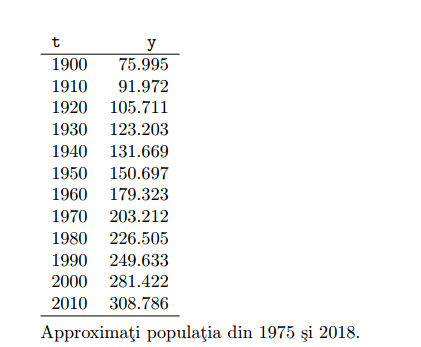

t = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75995 91972 105711 123203 131669 150697 179323 203212 226505 249633 281422 308786];

approx_1975 = Lagrange(1975, t, y);
approx_2018 = Lagrange(2018, t, y);

fprintf('Population in 1975: %.4f\n', approx_1975);

Population in 1975: 214364.3888


fprintf('Population in 2018: %.4f\n', approx_2018);

Population in 2018: -664306.8132


% Runge phenomenon for this huge degree polynomial
% 1975 appears to be ok because it is in the studied interval
% but the 2018 population is far off because the year being on the edge of
% the interval

% An easy fix would be the studying of the interpolation of a smaller
% polynomial, closer to 2018
t_closer = [1990 2000 2010];
y_closer = [249633 281422 308786];
approx_2018_closer = Lagrange(2018, t_closer, y_closer);
fprintf('Population in 2018 (closer): %.4f\n', approx_2018_closer);

Population in 2018 (closer): 327491.2000
